# Graficas de comparativas de los controladores

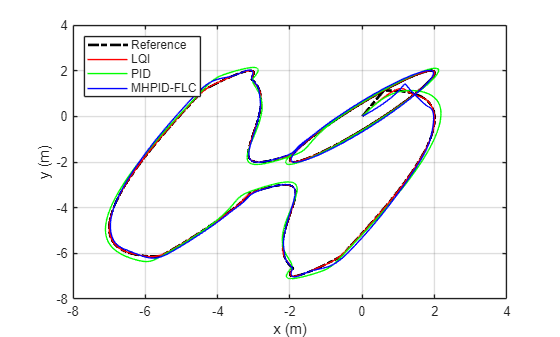

clear, clc
% posicion
load("r_lqi.mat")
load("r_pid.mat")
load("r_mhpid.mat")
% actitud
load("eta_lqi.mat")
load("eta_pid.mat")
load("eta_mhpid.mat")

t = r_pid.Time;
x = -0.5*max(0,min(t-25,10)) + 0.5*max(0,min(t-55,10)) - 2*sin(0.1*pi.*t + 0.3).*(t>=10);
y = -0.5* max(0, min(t-10, 10)) + 0.5 * max(0, min(t-40, 10))  - 2*sin(0.1*pi.*t + 0.6).*(t>=10);
z = 1.5 + 0.1*sin(0.02*pi.*t + 0.3).*(t>=10);

plot(x,y,'LineStyle','-.','LineWidth',2,'Color','black')
grid on
hold on
plot(r_lqi.Data(1,:), r_lqi.Data(2,:),'Color','r')
plot(r_pid.Data(1,:), r_pid.Data(2,:),'Color','g')
plot(r_mhpid.Data(1,:), r_mhpid.Data(2,:),'Color','b')

legend('Reference', 'LQI', 'PID', 'MHPID-FLC', 'Location','northwest')
xlabel('x (m)')
ylabel('y (m)')